# Perturbation with Khalil

This script uses the polar coordinate representation of states in phase space, $(r,\theta)$ and demonstrates a perturbation approach to showing that $r(t)$ increases on average. We use the fact that $\dot{\theta} < 0$ to say that there is a reparameterization of time $t(\theta)$, yielding a new dynamical system


$$\dot{\hat{r}}(\theta) = \frac{\dot{r}(t(\theta))}{\dot{\theta}(t(\theta))}$$


which is of the form 


$$\dot{\hat{r}} = P(\theta, \hat{r}, I) + IC(\theta,\hat{r},I)$$


Using Khalil's perturbation method (chapter 10), we can get an approximation of order $O(I^2)$ by using


$$\hat{r} \approx x_0(\theta) + Ix_1(\theta)$$


where


$$\begin{cases}
\dot{x_0}(\theta) = P(\theta, x_0, 0) \\
x_0(0) = r_0
\end{cases}$$



$$\begin{cases}
\dot{x_1}(\theta) = \frac{\partial P}{\partial \hat{r}}(\theta, x_0(\theta),0)x_1 + \frac{\partial P}{\partial I}(\theta, x_0(\theta),0) = a(\theta)x_1 + b(\theta) \\
 x_1(0) = 0
\end{cases}$$


This script computes $x_0(\theta)$ and $x_1(\theta)$ and plots them with the terms $a(\theta)$ and $b(\theta)$.

close all;
clc;

% Set the physical dynamics of the acrobot
mass = 1; % kg
len = 1; % m
gravity = 1; % m/s^2
scale = min(1,sqrt(3/(10*mass^2*gravity*len^3)));

% Set the ode solver options
baseOptions = odeset('RelTol',10^-13,'AbsTol',10^-13,'OutputFcn',@odephas2);
r0 = 1; % Initial radius
T0 = 0; T1 = pi; % Time frame of solution [T0, T1]

% Option to compute x1(pi) for all initial conditions
% (which is very time-consuming)
RUN_SENSITIVITY_ANALYSIS = false;

% Set the symbolic variables for dynamics
m = sym('m','positive'); % mass of each link
g = sym('g','positive'); % gravitational acceleration
l = sym('l','positive'); % length of the acrobot's links
I = sym('I','positive'); % scaling of the actuator
t = sym('t'); % angle in (qu,pu) plane
r = sym('r'); % radius in (qu,pu) plane
% Set the actuator symbolically
qa = atan(I*r*sin(t));
% Define some shorthand variables
st = sin(t);
ct = cos(t);
sa = sin(qa);
ca = cos(qa);
Irst1 = (1+I^2*r^2*st^2);
R = sin(r*ct)*(2+ca) + cos(r*ct)*sa;
L = [(1+ca)*I, (3+2*ca)*Irst1];
Lnum = L * [ct;-st];
Lden = L * [st; ct];
% Compute the numerators of r_dot(t) and theta_dot(t)
rdnum = -r*(Irst1*r*st*ct + m^2*g*l^3*Lnum*R);
tdnum = (Irst1*r*st^2 + m^2*g*l^3*Lden*R);
% Compute the dynamics r_hat_dot
rhd = rdnum/tdnum;

% Compute x0_dot = P(theta,r,0)
rhd0 = simplify(subs(rhd,I,0));
% Compute dP/dr(theta,r,0), which is a(theta)
% when r = x0(theta)
rhd1r = simplify(subs(diff(rhd,r),I,0));
% Compute dP/dI(theta,r,0), which is b(theta)
% when r = x0(theta)
rhd1I = simplify(subs(diff(rhd,I),I,0));

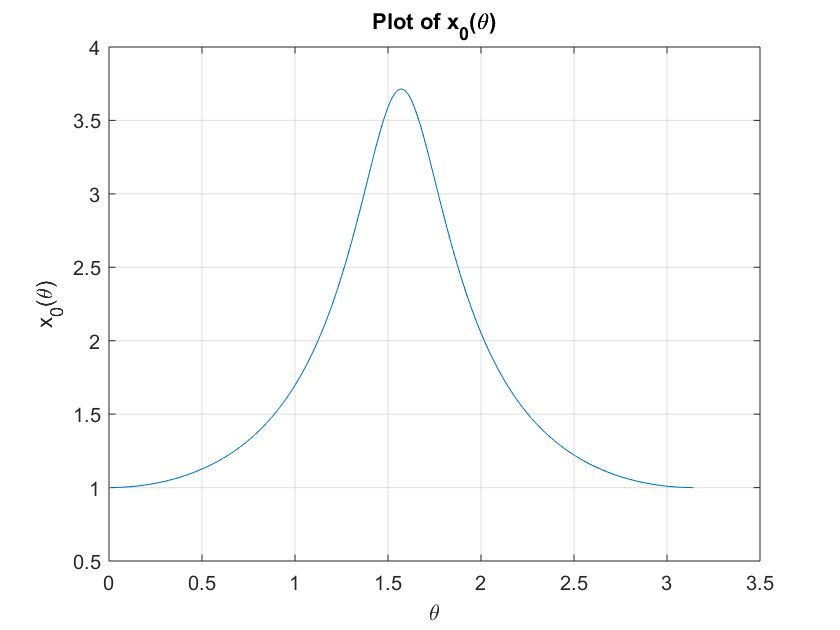

% Sub in the dynamics for x0 and the terms in x1
x0df = matlabFunction(...
    subs(rhd0, [m g l], [mass gravity len]), ...
    'vars',[t r]);
rhd1rf = matlabFunction(...
    subs(rhd1r, [m g l], [mass gravity len]), ...
    'vars',[t r]);
rhd1If = matlabFunction(...
    subs(rhd1I, [m g l], [mass gravity len]), ...
    'vars', [t r]);
x1df = @(t,x) rhd1rf(t,x(1))*x(2) + rhd1If(t,x(1));
% Simulate x0(theta) and the true x1
fx0x1 = @(t,x) [x0df(t,x(1)); x1df(t,x)]; 
sol = ode45(fx0x1, [T0; T1], [r0; 0], baseOptions);
thetas = sol.x;
x0 = sol.y(1,:);
x1 = sol.y(2,:);

% Plot x0
figure;
plot(thetas, x0);
title('Plot of x_0(\theta)');
xlabel('\theta');
ylabel('x_0(\theta)');
grid on;

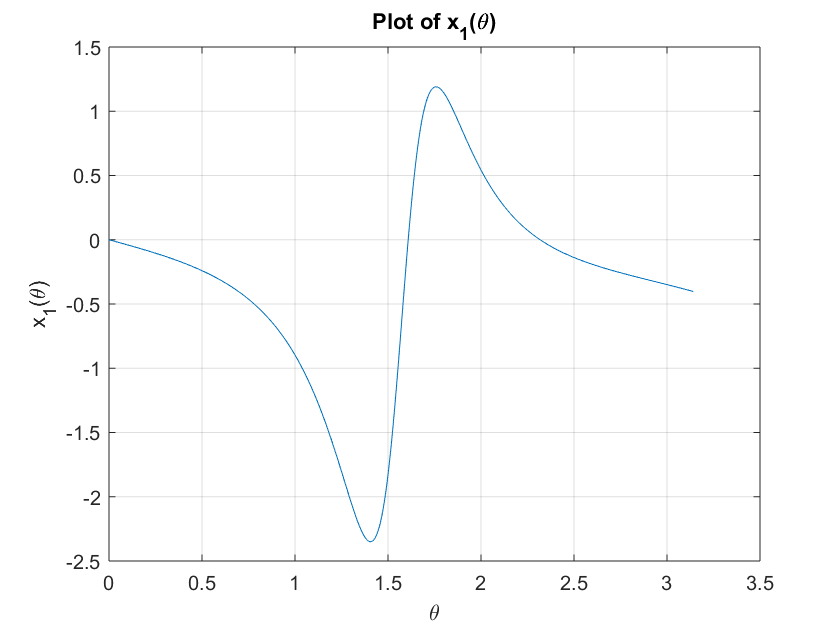


% Plot the true x1
figure;
plot(thetas, x1);
title('Plot of x_1(\theta)');
xlabel('\theta');
ylabel('x_1(\theta)');
grid on;


x1Diff = x1(end) - x1(1)

x1Diff = -0.4029

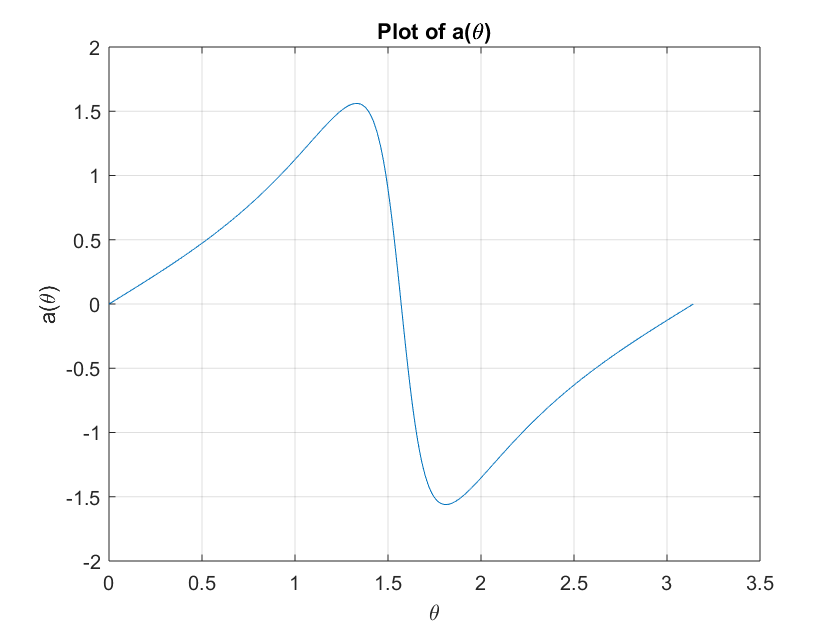


% Compute a(theta) along the solution to x0(theta)
% and plot
atheta = rhd1rf(thetas,x0);
figure;
plot(thetas, atheta);
title('Plot of a(\theta)');
xlabel('\theta');
ylabel('a(\theta)');
grid on;

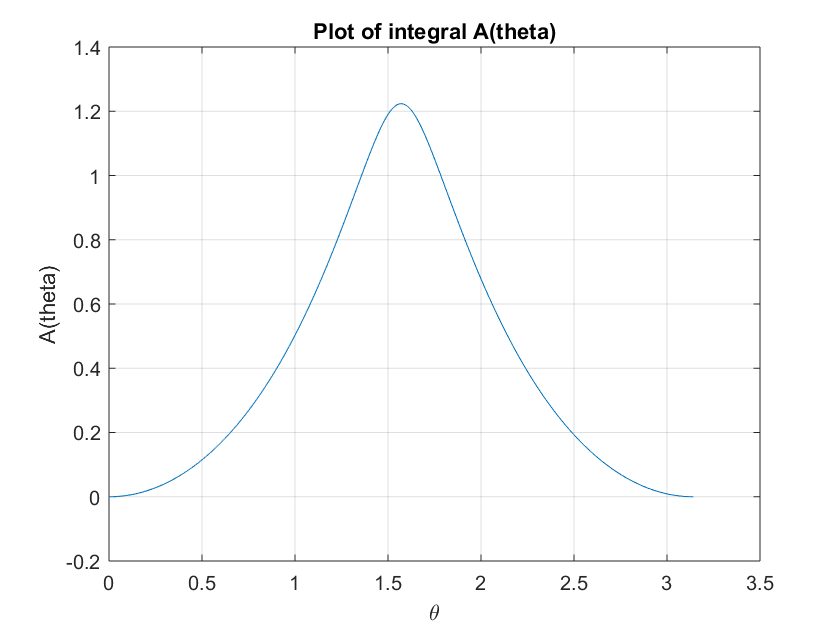


% Compute the integral to a(theta) and show that
% it is periodic, symmetric, and both starts and ends
% at 0.
Atheta = cumtrapz(thetas, atheta);
figure;
plot(thetas, Atheta);
title('Plot of integral A(theta)');
xlabel('\theta');
ylabel('A(theta)');
grid on;


Adiff = Atheta(end) - Atheta(1)

Adiff = -1.2080e-06

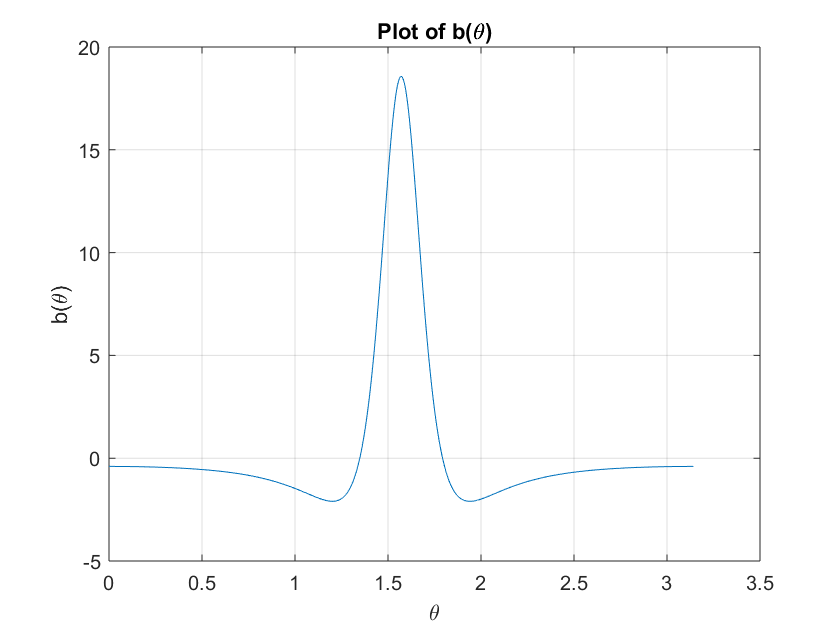


% Compute b(theta) along the solution to x0(theta)
% and plot
btheta = rhd1If(thetas, x0);
figure;
plot(thetas, btheta);
title('Plot of b(\theta)');
xlabel('\theta');
ylabel('b(\theta)');
grid on;

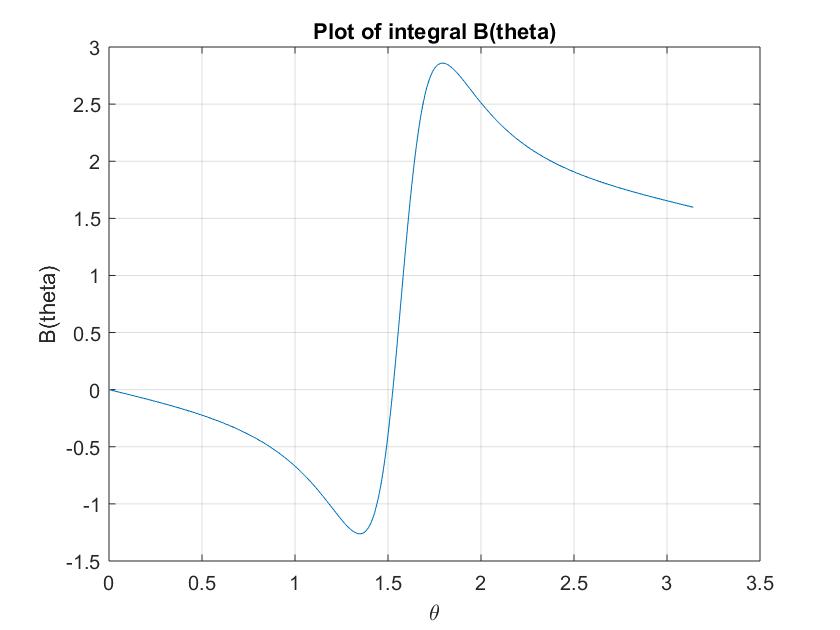


% Now compute the integral of b(theta). Is it negative?
% Positive?
Btheta = cumtrapz(thetas, btheta);
figure;
plot(thetas, Btheta);
title('Plot of integral B(theta)');
xlabel('\theta');
ylabel('B(theta)');
grid on;


Bdiff = Btheta(end) - Btheta(1)

Bdiff = 1.5967


% Compute now our model for x1(pi), which is
% integral_0^pi exp{-A(tau)}b(tau)dtau. We will assert
% that this is the same as what we got from ode45.
% Note: this is NOT the same as x1(theta) since the actual
% integral is 
% x1(t) = integral_0^t exp(A(t)-A(tau))b(tau)dtau
expAbintegral = cumtrapz(thetas,exp(-Atheta).*btheta);
x1modelpi = expAbintegral(end);
x1pi = x1(end);
x1Diff = abs(x1pi - x1modelpi) < 10e-6

x1Diff = logical
   0


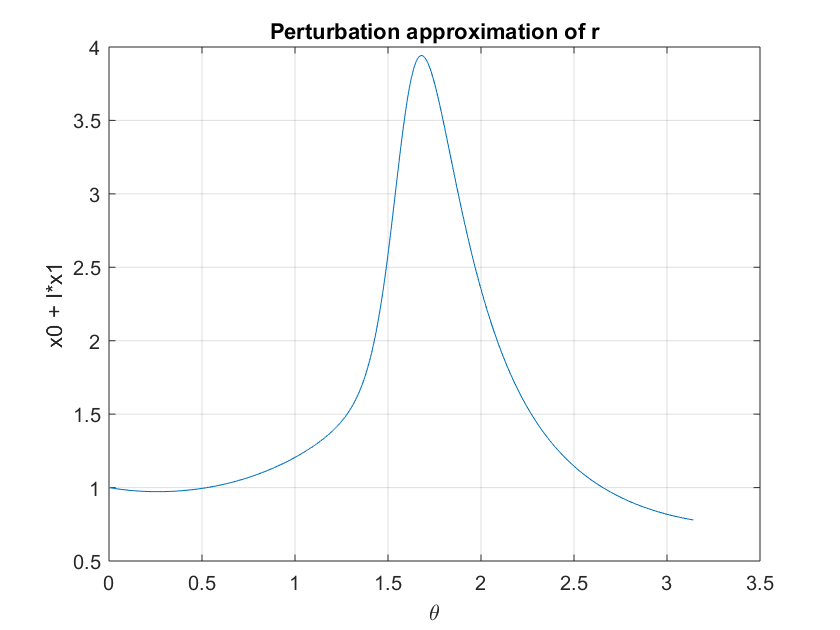

% Finally, plot x0 + Ix1 which is the approximation to r
% and show it decreases along theta (which means it would
% increase over time).
rapprox = x0 + scale*x1;
figure;
plot(thetas,rapprox);
title('Perturbation approximation of r');
xlabel('\theta');
ylabel('x0 + I*x1');
grid on;


Rdiff = rapprox(end) - rapprox(1)

Rdiff = -0.2207

if RUN_SENSITIVITY_ANALYSIS
% Show x1(pi) decreases as x0(0) increases.
% Create a storage container for x1(pi)
n = 1000;
x1s = zeros(1,n);
% Create a list of initial conditions. Note that we
% use initial conditions only up to 3 and not
% pi, since x1(pi) blows up to -inf near pi.
r0s = linspace(0,3,n);
% Iterate over the initial conditions and solve for x1(pi)
for j = 1:length(r0s)
xsoli = ode45(fx0x1, [0 pi], [r0s(j) 0], baseOptions);
x1s(j) = xsoli.y(2,end);
end
% Plot x1(pi) against the initial condition
figure;
plot(r0s,x1s)
xlabel('x_0(0)');
ylabel('x_1(\pi)');
title('x_1(\pi) decreases as x_0(0) increases');
end